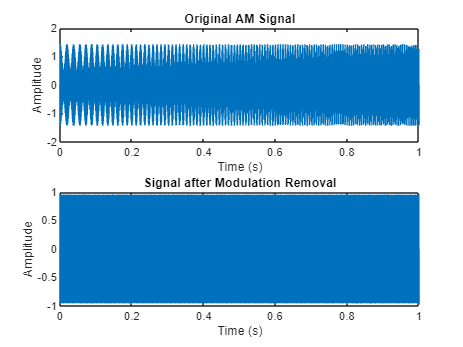

fs = 1e4;
t = 0:1/fs:1;
y_mod = 0.5 * chirp(t, 50, t(end), 200);
y_carr = sin(2 * pi * t * 1e3);
y = y_mod .* y_carr + y_carr;
% Calculate the envelope
y_env = abs(hilbert(y));

% Remove the modulation by dividing the original signal by its envelope
y_demod = y - y_env;

% Plot the spectra
figure;
subplot(2, 1, 1);
plot(t, y);
title('Original AM Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(t, y_demod);
title('Signal after Modulation Removal');
xlabel('Time (s)');
ylabel('Amplitude');

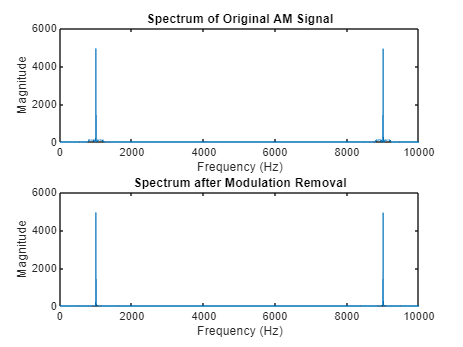


% Frequency domain analysis
Y = fft(y);
Y_demod = fft(y_demod);

f = (0:length(Y)-1) * fs / length(Y);

figure;
subplot(2, 1, 1);
plot(f, abs(Y));
title('Spectrum of Original AM Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(2, 1, 2);
plot(f, abs(Y_demod));
title('Spectrum after Modulation Removal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

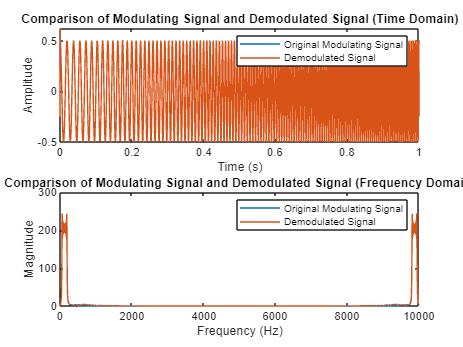

% Multiply the modulated signal by the carrier signal
y_demod = y .* y_carr;

% Apply a low-pass filter with a cut-off frequency of 400 Hz
fpass = 400;
y_filt = lowpass(y_demod, fpass, fs);

% Remove the constant component
y_filt = y_filt - mean(y_filt);

% Correct for the lost modulation band
y_filt = y_filt * 2;

% Plot time and frequency domain comparison
figure;
subplot(2, 1, 1);
plot(t, y_mod);
hold on;
plot(t, y_filt);
hold off;
title('Comparison of Modulating Signal and Demodulated Signal (Time Domain)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original Modulating Signal', 'Demodulated Signal');

subplot(2, 1, 2);
Y_mod = fft(y_mod);
Y_filt = fft(y_filt);

plot(f, abs(Y_mod));
hold on;
plot(f, abs(Y_filt));
hold off;
title('Comparison of Modulating Signal and Demodulated Signal (Frequency Domain)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Original Modulating Signal', 'Demodulated Signal');

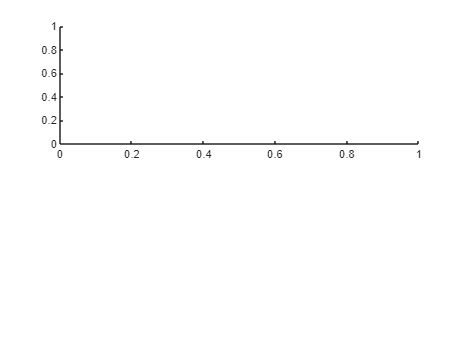

fs = 2e5;
fc = 1e4;
t = 0:1/fs:1;
y_mod = sin(2 * pi * t * 500);
y = sin(2 * pi * t * fc + y_mod);
dt = 1/fs;

% Calculate the derivative of the signal
y_diff = diff(y) / dt;

% Calculate the envelope of the derivative signal
y_env = abs(hilbert(y_diff));

% Remove the constant component
y_env = y_env - mean(y_env);

% Integrate the signal to compensate for phase shift
y_dem = inteFD(y_env, 1/fs);

% Plot time and frequency domain comparison
figure;
subplot(2, 1, 1);

plot(t, y_mod);

Error using plot
Vectors must be the same length.

hold on;
plot(t(1:end-1), y_dem);
hold off;
title('Comparison of Modulating Signal and Demodulated Signal (Time Domain)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original Modulating Signal', 'Demodulated Signal');

subplot(2, 1, 2);
Y_mod = fft(y_mod);
Y_dem = fft(y_dem);

plot(f, abs(Y_mod));
hold on;
plot(f, abs(Y_dem));
hold off;
title('Comparison of Modulating Signal and Demodulated Signal (Frequency Domain)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Original Modulating Signal', 'Demodulated Signal');
load('40Hz.mat');
load('100Hz.mat');
load('150Hz.mat');
load('40Hz_ref.mat');
% Example for 40 Hz signal
fs = 2e5; % Assuming the same sampling rate as in Task 3
y = bandpass(y, [0.8e5, 1.2e5], fs);

% Remove amplitude modulations
y_env = abs(hilbert(y));
y_demod = y ./ y_env;

% Frequency demodulation
dt = 1/fs;
y_diff = diff(y_demod) / dt;
y_env = abs(hilbert(y_diff));
y_env = y_env - mean(y_env);
y_dem = inteFD(y_env, 1/fs);

% Low-pass filtering
y_dem = lowpass(y_dem, 800, fs);

% Clipping the data vector to remove artifacts
y_dem = y_dem(100:end-100); % Adjust the range as needed

% Display waveforms and spectra
figure;
subplot(2, 1, 1);
plot(t_meas, y_meas);
hold on;
plot(t_meas, y_dem);
hold off;
title('Comparison of Reference and Demodulated Signal (Time Domain)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Reference Signal', 'Demodulated Signal');

subplot(2, 1, 2);
Y_meas = fft(y_meas);
Y_dem = fft(y_dem);

plot(f, abs(Y_meas));
hold on;
plot(f, abs(Y_dem));
hold off;
title('Comparison of Reference and Demodulated Signal (Frequency Domain)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Reference Signal', 'Demodulated Signal');
